# **Unsupervised statistical image segmentation using bi-dimensional hidden Markov chains model with application to mammography images**

**A PROJECT REPORT**

*Submitted by*

**Advaith Krishna                    - CB.SC.U4AIE24203**

**Amudala Jashwanth             - CB.SC.U4AIE24204 **

**Bhuvan Rajasekar                 - CB.SC.U4AIE24209**

**Sachcith G N                         -CB.SC.U4AIE24251**

Course Code

**22MAT230 - Mathematics for Computing - 4 (MFC - 4)**

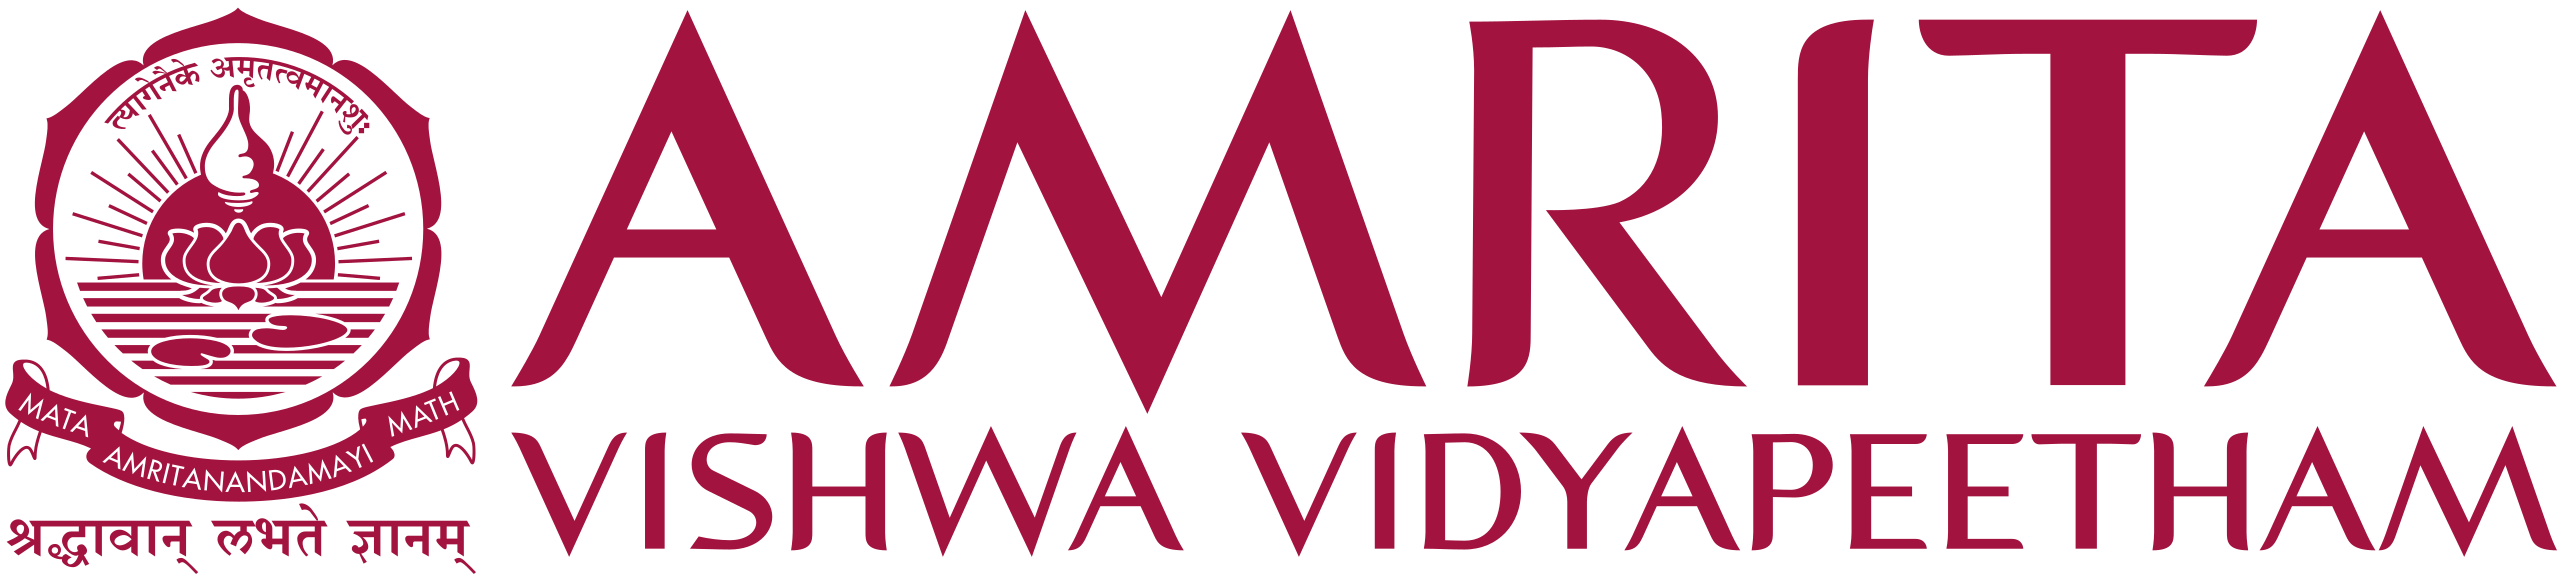

**AMRITA SCHOOL OF ARTIFICIAL INTELLIGENCE**

**Ettimadai,COIMBATORE-641112**

**AMRITA SCHOOL OF ARTIFICIAL INTELLIGENCE**

**AMRITA VISHWA VIDYAPEETHAM**

**COIMBATORE-641112**

**DECLARATION**

We, **Advaith Krishna - CB.SC.U4AIE24203, Amudala Jashwanth - CB.SC.U4AIE24204, Bhuvan Rajasekar - CB.SC.U4AIE24209 and Sachcith G N - CB.SC.U4AIE24251 **hereby declare that the project work entitled “***ADMM-based Distributed Electric Vehicle Charging Optimisation Algorithm***” is the record of the original work done by us under the guidance of **Dr. Sunil Kumar S**, Assistant Professor, School of Artificial Intelligence, Amrita Vishwa Vidhyapeetham, Coimbatore.

**                Advaith Krishna                    - CB.SC.U4AIE24203                                                                Amudala Jashwanth             - CB.SC.U4AIE24204 **

**                Bhuvan Rajasekar                - CB.SC.U4AIE24209                                                                Sachcith G N                           -CB.SC.U4AIE24251**

**Place:**Coimbatore – 641112

**Date****: 19/01/2026**

**COUNTERSIGNED**

**Dr. Sunil Kumar S, **

Assistant Professor, 

Department of Artificial Intelligence

## [Base Paper Link](https://www.sciencedirect.com/science/article/pii/S1319157823002690)

## Introduction

Medical image analysis plays a crucial role in modern healthcare systems, especially in the early detection of diseases such as breast cancer. Mammography images are widely used by radiologists to detect abnormal tissues and tumor regions. However, manual interpretation of mammogram images is time-consuming, subjective, and highly dependent on the expertise of the doctor.

Automatic image segmentation techniques help in identifying suspicious regions accurately and efficiently. One of the major challenges in mammogram image segmentation is the presence of noise, low contrast, and overlapping intensity values between normal and abnormal tissues.

Hidden Markov Model (HMM) based segmentation methods have been widely used for statistical image segmentation. However, classical HMM approaches treat images as one-dimensional sequences, which leads to loss of spatial information. The research paper being implemented in this project proposes a **Bi-Dimensional Hidden Markov Chain (2D-HMC) model**, which preserves neighborhood relationships and improves segmentation quality.

## Objective

To develop an automated image segmentation system for mammography images using the **Bi-Dimensional Hidden Markov Chain (2D-HMC) model**.

## Work done till now

Loading and visualising mammography images in MATLAB.

Perform basic image preprocessing operations such as:

- Grayscale conversion

- Image normalisation

Converting the 2D image into a suitable representation (2D - 1D) for HMM processing.

Extract pixel intensity information required for the observation sequence.

## Expected Outcome

Input Mammogram Image

        ↓

Image Preprocessing  

        ↓

2D to 1D Conversion (Scanning)

        ↓

Bi-Dimensional Observation Formation

        ↓

Parameter Estimation using 2D-HMC

        ↓

Hidden State Estimation

        ↓

Tumor Region Segmentation

        ↓

Performance Evaluation

## Dataset Description

## [Dataset - Multi Organ CT Scan Images (With abnormal)](https://www.kaggle.com/code/ipythonx/medicai-3d-btcv-segmentation-in-keras)

The dataset consists of **3D Computed Tomography (CT) scan images** of the human abdomen. Unlike simple 2D images, each sample in the dataset is a volumetric medical image composed of multiple sequential slices that together form a complete three-dimensional representation of internal organs.

Each sample contains:

- A 3D grayscale CT image volume

- A corresponding segmentation mask (ground truth)

- Pixel-wise annotations for multiple anatomical structures

**Data Format**

The images and masks are stored in standard medical imaging formats:

- NIfTI (.nii / .nii.gz) format for volumetric CT scans

- Each volume contains a stack of 2D slices

- Typical slice resolution: approximately 512 × 512 pixels

- Number of slices per volume varies depending on the scan

clear all;close all;clc;clearvars;clf;

## Helper Functions

### **Image_Preprocessing**

The function **Image_Preprocessing** reads an input image and crops it to a square shape if necessary. It then converts the image to grayscale and changes the pixel values to double precision. Finally, the intensity values are normalized from the range 0–255 to 0–1.

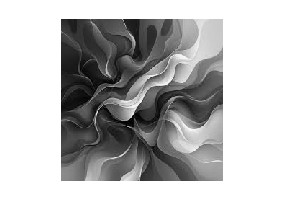

function Y = Image_Preprocessing(I)
    I = imread(I);
    [m,n]=size(I);
    if m~=n
        I=I(1:min(m,n),1:min(m,n),:);
    end

    I = double(rgb2gray(I));
    Y=I/255;
end

### 2D to 1D and vise versa

The function **twodim2onedim** converts a 2D image into a 1D column vector using column-wise scanning and also computes a second vector representing the average of vertical neighbors. The function **onedim2twodim** performs the reverse operation by reshaping a 1D vector back into its original 2D image form.

function [Y1,Y2] = twodim2onedim(I)
    [m,n] = size(I);
    Y1 = reshape(I,m*n,1);
    temp1 = [zeros(m,1);Y1(1:end-m)];
    temp2 = [Y1(m+1:end);zeros(m,1)];
    Y2 = (temp1+temp2)/2;
end

function Y = onedim2twodim(I,m,n)
    Y = reshape(I,m,n);
end

### Compute Normal Distribution Function

Computes the 2-dimensional Gaussian (normal) distribution for each pixel and for each class. It treats the two inputs $Y_n^1$ and $Y_n^2$ as the two variables of the distribution and uses the given class-wise means $\mu$ and covariance matrices $\Sigma$ to compute the likelihood. The output is a matrix $f(Y_n^1,Y_n^2)$ of size (number of pixels (N) × number of classes (K)) containing the observation probabilities.So, 

$\mathbf{f} \left( i, j \right) = i^{th} \text{ pixel's } j^{th} \text{ class's Likelihood}$.

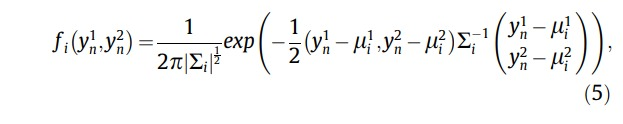

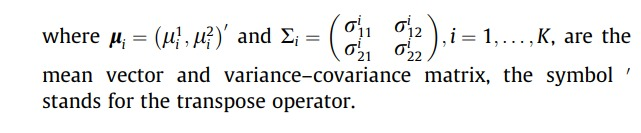

function f = compute_f(Y1,Y2,mu,sig)
    [k,~] = size(mu);
    [n,~] = size(Y1);
    f = zeros(n,k);
    current_sig = zeros(2,2);
    for i=1:k
        temp = [Y1,Y2]-mu(i,:);
        current_sig(:,:) = sig(i,:,:);
        D = 1/(2*pi*sqrt(det(current_sig)));
        f(:,i) = D*exp(-0.5*sum((temp*pinv(current_sig)).*temp,2));
    end
end

### Create Transition and Initial Probabilities

This function generates random initial parameters for the Hidden Markov Model. It creates:

- a **state transition matrix **`a` of size $K x K$ normalised so that each row sums to 1, and

- an **initial state probability vector **$\pi$ derived from the random values.

These are used as starting values for the HMM algorithm.

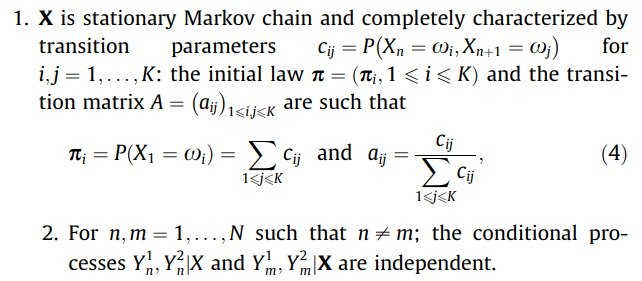

function [a,PI] = create_a_pi(k)

iteration = 100

    a = rand(k,k);
    PI = sum(a,2)';
    a = a./sum(a,2);
end

### Compute Forward Probabilities $(\alpha)$ and Backward Probabilities $(\beta)$

The function **compute_alpha **calculates the forward probability matrix $(\alpha)$ for the HMM using the Forward algorithm. It recursively computes the probability of observing the sequence up to each pixel for every class, using the initial probabilities, transition matrix, and observation likelihoods. The result is a normalised matrix of size (number of pixels (N) × number of classes (K)).

The function **compute_beta** implements the Backward algorithm to compute the backward probability matrix $(\beta)$. It calculates the probability of observing the remaining sequence from each pixel position for every class, moving from the end of the sequence to the beginning. The output is a normalised matrix of size (number of pixels (N) × number of classes (K)).

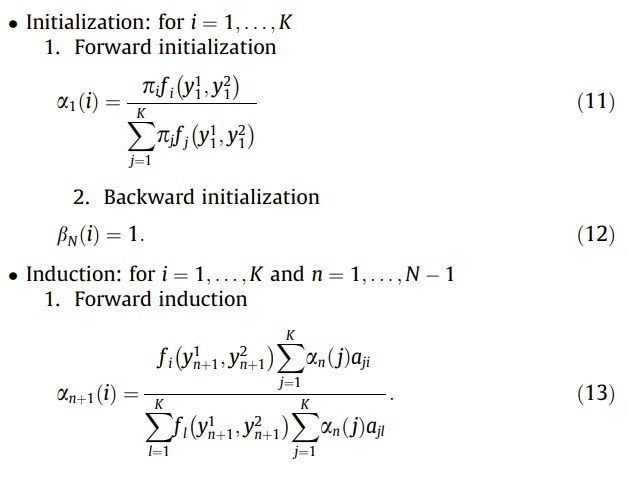

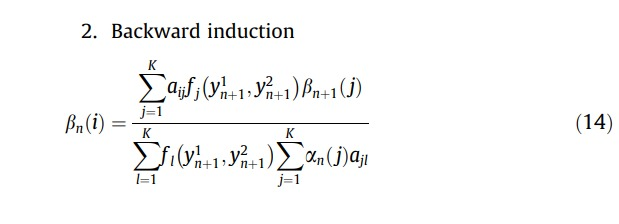

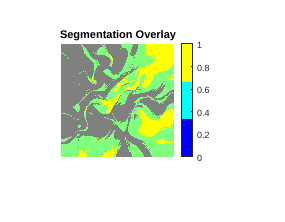

function alpha = compute_alpha(PI,a,f)
    [n,k] = size(f);
    alpha = zeros(n,k);
    alpha(1,:) = PI(1,:).*f(1,:);
    alpha(1,:) = alpha(1,:)./sum(alpha(1,:));
    for i=2:n
        % alpha(i,:) = f(i,:).*alpha(i-1,:).*sum(a,2)';
        alpha(i,:) = f(i,:).*(alpha(i-1,:)*a);

        alpha(i,:) = alpha(i,:)./sum(alpha(i,:));
    end
end

function beta = compute_beta(a,f,alpha)
    [n,k] = size(f);
    beta = zeros(n,k);
    beta(end,:) = ones(1,k);
    for i=n-1:-1:1
        beta(i,:) = sum(a.*f(i+1,:).*beta(i+1,:),2)';
        % beta(i,:) = beta(i,:)./(sum(f(i+1,:).*sum(alpha(i,:).*a,2)'));
        beta(i,:) = beta(i,:)./(sum(f(i+1,:).*(alpha(i,:)*a)));
    end
end

### Compute Posterior Probabilities $(\psi  \&  \chi)$

This function computes two important posterior probability terms used in HMM parameter estimation**:**

- $(\psi)$ **- phi:**  the joint probability of transitioning from state iii to state jjj at each pixel position,

- $(\chi)$** - chi:** the marginal probability of each state at each pixel.

These values are derived from the forward (α), backward (β), transition matrix, and observation probabilities, and are later used in the Expectation-Maximization (EM) update steps.    

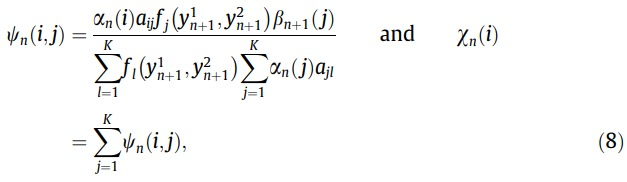

function [psi,chi] = compute_psi_chi(alpha,beta,a,f)
    [n,k] = size(f);
    psi = zeros(n,k,k);
    chi = zeros(n,k);
    temp = zeros(k,k);
    for pixel=1:n-1
        for i=1:k
            for j=1:k
                psi(pixel,i,j) = alpha(pixel,i)*a(i,j)*f(pixel+1,j)*beta(pixel+1,j);
            end
        end
        % psi(pixel,:,:)=psi(pixel,:,:)./(sum(f(pixel+1,:).*sum(alpha(pixel,:).*a,2)'));
        psi(pixel,:,:)=psi(pixel,:,:)./(sum(f(pixel+1,:).*(alpha(pixel,:)*a)));
        temp(:,:) = psi(pixel,:,:);
        chi(pixel,:) = sum(temp,2)';
        chi(pixel,:) = chi(pixel,:)./sum(chi(pixel,:));
    end
end

## Main Function

clear all;close all;clc;clearvars;clf;

fullPath = matlab.desktop.editor.getActiveFilename;
scriptFolder = fileparts(fullPath);
Image = Image_Preprocessing(fullfile(scriptFolder,'Test.jpeg'));
imshow(Image)
mu = [0 0;1 1;2 2];
sigma = zeros(3,2,2);
sigma(1,:,:) = [1 0;0 1];
sigma(2,:,:) = [2,1;1,2];
sigma(3,:,:) = [1 0;0 1];


% Image = 1:9;
% Image = Image./max(max(Image));
% Image = reshape(Image,3,3);
[A1,A2] = twodim2onedim(Image);

f = compute_f(A1,A2,mu,sigma);
[aij,PI] = create_a_pi(3);
alpha = compute_alpha(PI,aij,f);
beta = compute_beta(aij,f,alpha);
[psi,chi] = compute_psi_chi(alpha,beta,aij,f);

maxIter = 1e2;
[n,k] = size(f);
aij_new = aij;
for iteration=1:maxIter
    PI_new = sum(chi)/n;
    % aij_new(:,:) = sum(psi)./sum(chi);
    aij_new = zeros(size(aij));
    for i=1:k
        for j=1:k
            aij_new(i,j) = sum(psi(:,i,j)) / sum(chi(:,i));
        end
    end
    mu_new = [sum(chi.*A1);sum(chi.*A2)]./sum(chi);
    mu_new = mu_new';
    sigma_new = zeros(size(sigma));
    for i=1:k
        temp = [A1-mu_new(i,1) A2-mu_new(i,2)];
        temp2 = zeros(2,2,n);
        temp2(1,1,:) = temp(:,1).*temp(:,1);
        temp2(1,2,:) = temp(:,1).*temp(:,2);
        temp2(2,1,:) = temp(:,2).*temp(:,1);
        temp2(2,2,:) = temp(:,2).*temp(:,2);
        sigma_new(i,:,:) = sum(temp2,3)/sum(chi(:,i));
    end
    f = compute_f(A1,A2,mu_new,sigma_new);
    alpha = compute_alpha(PI_new,aij_new,f);
    beta = compute_beta(aij_new,f,alpha);
    [psi,chi_new] = compute_psi_chi(alpha,beta,aij_new,f);
    if norm(chi-chi_new,"fro")<1e-3
        norm(chi-chi_new,"fro")
        disp("Converged");
        break;
    end
    chi = chi_new;
    PI = PI_new;
    aij = aij_new;
    mu = mu_new;
    sigma = sigma_new;
end
iteration


[~, labels] = max(chi, [], 2);
seg_image = reshape(labels, 225,225);


figure;
imshow(Image);hold on;
h = imagesc(seg_image);
set(h, 'AlphaData', 0.5);
colormap(jet(k));
colorbar;
axis image off;
title('Segmentation Overlay');

## Testing

% function em = EM()
% fullPath = matlab.desktop.editor.getActiveFilename;
% scriptFolder = fileparts(fullPath);
% Image = Image_Preprocessing(fullfile(scriptFolder,'Test.jpeg'));
% imshow(Image)
% [oned,Y2] = twodim2onedim(Image)
% [m,n] = size(Image);
% twod = onedim2twodim(oned,m,n);
% imshow(twod);
% sum(Image(:,1)==oned(1:length(Image(:,1))))/length(Image(:,1))
% sum(Image(1,:)==oned(1:length(Image(1,:))))/length(Image(1,:))